clear all 
clc

INPUT

% Force
p=200; % N
% lengths determined by trial and error in ADAMS
r1=0.11;
r2=0.07;
r5=0.1164;
r1_bar=0.17;
O3C=0.3;


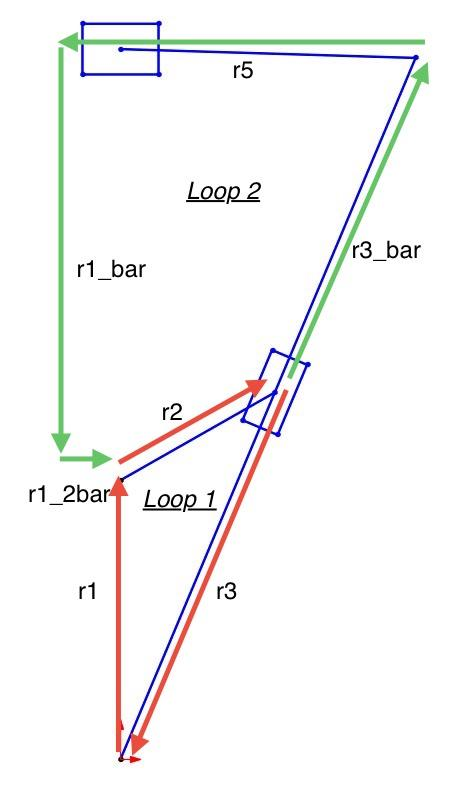


%Constant angles
theta1=pi/2;
theta1_bar=1.5*pi;
theta1_2bar=0;

N=2000;
theta2=linspace(0,4*pi,N);

% Initial conditions for theta_2 = 0 (Found from SOLIDWORKS)
theta3_1=deg2rad(180+57);
theta3bar_1=deg2rad(57);
theta5_1=deg2rad(166);
r1_2bar_1=0;
r3_1=0.13038;
r3_bar_1=0.3-r3_1;

w2=1 ; % 1 rad/sec : input angular velocity
a2=0; %input angular acceleration (=0 Given Data)

NEWTON-RAPHSON CONTROLLERS

maxiter=100;
res=0.0001;

function [x,y,loop_break] = newtonraphson(f,g,jacob,x,y,maxiter,res,x1,y1)
delta=inf(2,1);
z=[x1;y1];
iter=1;
loop_break=false;
while abs(delta(1,1))>res || abs(delta(2,1))>res
    delta=double(-jacob(x1,y1)\[f(x1,y1);g(x1,y1)]);
    z=z+delta;
    x1=z(1,1);
    y1=z(2,1);
    iter=iter+1;
    if iter>maxiter
        disp('issue')
        loop_break=true;
        break
    end
end
x=z(1,1);
y=z(2,1);
end

     POSTURE

syms Theta2 Theta3 R3 Theta5 R1_2b Theta3_b r3_b


f1(Theta3,R3,Theta2)=r2*cos(Theta2)+R3*cos(Theta3)+r1*cos(theta1);
g1(Theta3,R3,Theta2)=r2*sin(Theta2)+R3*sin(Theta3)+r1*sin(theta1);
jacob1(Theta3,R3,Theta2)=[diff(f1,Theta3),diff(f1,R3);diff(g1,Theta3),diff(g1,R3)];

f1_func = matlabFunction(f1, 'Vars', [Theta3,R3,Theta2]);
g1_func = matlabFunction(g1, 'Vars', [Theta3,R3,Theta2]);
jacob1_func = matlabFunction(jacob1, 'Vars', [Theta3,R3,Theta2]);


f2(Theta5,R1_2b,R3,Theta3,Theta2)=r2*cos(Theta2)+(O3C-R3)*cos(Theta3-pi)+r5*cos(Theta5)+r1_bar*cos(theta1_bar)+R1_2b*cos(theta1_2bar);
g2(Theta5,R1_2b,R3,Theta3,Theta2)=r2*sin(Theta2)+(O3C-R3)*sin(Theta3-pi)+r5*sin(Theta5)+r1_bar*sin(theta1_bar)+R1_2b*sin(theta1_2bar);
jacob2(Theta5,R1_2b,Theta2)=[diff(f2,Theta5),diff(f2,R1_2b);diff(g2,Theta5),diff(g2,R1_2b)];

f2_func = matlabFunction(f2, 'Vars', [Theta5,R1_2b,R3,Theta3,Theta2]);
g2_func = matlabFunction(g2, 'Vars', [Theta5,R1_2b,R3,Theta3,Theta2]);
jacob2_func = matlabFunction(jacob2, 'Vars', [Theta5,R1_2b,Theta2]);

r3=zeros(N,1);
teta3=zeros(N,1);
teta5=zeros(N,1);
r1_2b=zeros(N,1);

for i=1:N

    %loop1
    f1_handle = @(Theta3, R3) f1_func(Theta3, R3, theta2(i));
    g1_handle = @(Theta3, R3) g1_func(Theta3, R3, theta2(i));
    jacob1_handle = @(Theta3, R3) jacob1_func(Theta3, R3, theta2(i));    
    [teta_3,r_3,loop_break] = newtonraphson(f1_handle,g1_handle,jacob1_handle,Theta3,R3,maxiter,res,theta3_1,r3_1);
    teta3(i)=teta_3;
    r3(i)=r_3;
    theta3_1=teta_3;
    r3_1=r_3;    
    if loop_break, break, end

    %loop2
    f2_handle = @(Theta5,R1_2b) f2_func(Theta5,R1_2b,r3(i),teta3(i),theta2(i));
    g2_handle = @(Theta5,R1_2b) g2_func(Theta5,R1_2b,r3(i),teta3(i),theta2(i));
    jacob2_handle = @(Theta5,R1_2b) jacob2_func(Theta5,R1_2b,theta2(i));    
    [teta_5,r_1_2b,loop_break] = newtonraphson(f2_handle,g2_handle,jacob2_handle,Theta5,R1_2b,maxiter,res,theta5_1,r1_2bar_1);
    teta5(i)=teta_5;
    r1_2b(i)=r_1_2b;
    theta5_1=teta_5;
    r1_2bar_1=r_1_2b;    
    if loop_break, break, end    

end

POSITION OF EACH POINT

p_O3=[0,0,0];
p_O2=[0,0.11,0];
p_B=zeros(N,3);
p_C=zeros(N,3);
p_D=zeros(N,3);

p_G2=zeros(N,3);
p_G3=zeros(N,3);
p_G4=zeros(N,3);
p_G5=zeros(N,3);
p_G6=zeros(N,3);

for i=1:N
    p_B(i,:)=p_O2+r2*[cos(theta2(i)),sin(theta2(i)),0];
    p_C(i,:)=p_O3+O3C*[cos(teta3(i)-pi),sin(teta3(i)-pi),0]; 
    p_D(i,:)=p_C(i,:)+r5*[cos(teta5(i)),sin(teta5(i)),0]; 

    p_G2(i,:)=p_O2+r2/2*[cos(theta2(i)),sin(theta2(i)),0];
    p_G3(i,:)=p_O3+O3C/2*[cos(teta3(i)-pi),sin(teta3(i)-pi),0]; 
    p_G4(i,:)=p_B(i,:);
    p_G5(i,:)=p_C(i,:)+r5/2*[cos(teta5(i)-pi),sin(teta5(i)-pi),0];
    p_G6(i,:)=p_D(i,:);
end

VELOCITY & ACCELERATION

teta3p=zeros(N,1);
r3p=zeros(N,1);
teta5p=zeros(N,1);
r1_2bp=zeros(N,1);

teta3pp=zeros(N,1);
r3pp=zeros(N,1);
teta5pp=zeros(N,1);
r1_2bpp=zeros(N,1);

for i=1:N
%velocity
    %loop1
    A1=[cos(teta3(i)),-r3(i)*sin(teta3(i));sin(teta3(i)),r3(i)*cos(teta3(i))];
    B1=r2*[sin(theta2(i));-cos(theta2(i))];
    v1=A1\B1;
    if det(A1)==0
        disp('singular v1');
    end
    teta3p(i)=v1(2);
    r3p(i)=v1(1);

    %loop2
   
    A2=[-r5*sin(teta5(i)),cos(theta1_2bar);r5*cos(teta5(i)),sin(theta1_2bar)];
    B2=[r2*sin(theta2(i)+r3p(i)*cos(teta3(i)-pi)+(O3C-r3(i))*teta3p(i)*sin(teta3(i)-pi));...
        r2*cos(theta2(i)-r3p(i)*sin(teta3(i)-pi)-(O3C-r3(i))*teta3p(i)*cos(teta3(i)-pi))]; %theta3p = theta3barp /// r3p=-r3barp
    v2=A2\B2;
    if det(A2)==0
        disp('singular v2');
    end
    teta5p(i)=v2(1);
    r1_2bp(i)=v2(2);    

%acceleration
    %loop1
    C1=r2*[cos(theta2(i));sin(theta2(i))] + r3p(i)*teta3p(i)^2*[cos(teta3(i));sin(teta3(i))] + 2*r3p(i)*teta3p(i)*[sin(teta3(i));-cos(teta3(i))];
    Ac1=A1\C1;
    teta3pp(i)=Ac1(2);
    r3pp(i)=Ac1(1);
    %loop2
    C2=[r2*cos(theta2(i))+r3pp(i)*cos(teta3(i)-pi)-2*r3p(i)*teta3p(i)*sin(teta3(i)-pi)+(O3C-r3(i))*(teta3pp(i)*sin(teta3(i)-pi)+(teta3p(i))^2*cos(teta3(i)-pi))+r5*teta5p(i)^2*cos(teta5(i));...
        r2*sin(theta2(i))+r3pp(i)*sin(teta3(i)-pi)+2*r3p(i)*teta3p(i)*cos(teta3(i)-pi)-(O3C-r3(i))*(teta3pp(i)*cos(teta3(i)-pi)-(teta3p(i))^2*sin(teta3(i)-pi))+r5*teta5p(i)^2*sin(teta5(i))];
    Ac2=A2\C2;
    teta5pp(i)=Ac2(1);
    r1_2bpp(i)=Ac2(2);    
end

w3=w2.*teta3p;
w4=w3;
w5=w2.*teta5p;
v6=w2.*r1_2bp;

a3=w2.^2.*teta3pp+a2.*teta3p;
a4=a3;
a5=w2.^2.*teta5pp+a2.*teta5p;
A6=w2.^2.*r1_2bpp+a2.*r1_2bp;

a_G2=zeros(N,3);
a_G3=zeros(N,3);
a_G4=zeros(N,3);
a_G5=zeros(N,3);
a_G6=zeros(N,3);

aD=zeros(N,3);
aB=zeros(N,3);
aC=zeros(N,3);
for i=1:N
    a_G2(i, :)=cross([0,0,a2],p_G2(i, :)-p_O2)+cross([0,0,w2],cross([0,0,w2],p_G2(i, :)-p_O2));
    aB(i, :)=cross([0,0,a2],p_B(i, :)-p_O2)+cross([0,0,w2],cross([0,0,w2],p_B(i, :)-p_O2));
    a_G3(i, :)=cross([0,0,a3(i)],p_G3(i, :)-p_O3)+cross([0,0,w3(i)],cross([0,0,w3(i)],p_G3(i, :)-p_O3));
    a_G4(i, :)=aB(i, :);
    aC(i, :)=cross([0,0,a3(i)],p_C(i, :)-p_O3)+cross([0,0,w3(i)],cross([0,0,w3(i)],p_C(i, :)-p_O3));
    a_G5(i, :)=aC(i, :)+cross([0,0,a5(i)],p_G5(i, :)-p_C(i, :))+cross([0,0,w5(i)],cross([0,0,w5(i)],p_G5(i, :)-p_C(i, :)));
    aD(i, :)=aC(i, :)+cross([0,0,a5(i)],p_D(i, :)-p_C(i, :))+cross([0,0,w5(i)],cross([0,0,w5(i)],p_D(i, :)-p_C(i, :)));
    a_G6(i, :)=aD(i, :);
end


DYNAMIC FORCE EQUATIONS

syms f12x f12y f42x f42y T f13x f13y f35x f35y f43x f43y f65x f65y f16y 
syms aG2x aG2y aG3x aG3y aG4x aG4y aG5x aG5y aG6x aG6y
syms alfa2 alfa3 alfa4 alfa5 alfa6
syms P_O2x P_O2y P_Bx P_By P_Cx P_Cy P_O3x P_O3y P_Dx P_Dy
syms P_G2x P_G2y P_G3x P_G3y P_G4x P_G4y P_G5x P_G5y P_G6x P_G6y
var=[f12x f12y f42x f42y T f13x f13y f35x f35y f43x f43y f65x f65y f16y];
unknowns = zeros(numel(var), 10);

P_O2 = [P_O2x,P_O2y,0];
P_B = [P_Bx,P_By,0];
P_C = [P_Cx,P_Cy,0];
P_D = [P_Dx,P_Dy,0];
P_O3 = [P_O3x,P_O3y,0];

P_G2 = [P_G2x,P_G2y,0];
P_G3 = [P_G3x,P_G3y,0];
P_G4 = [P_G4x,P_G4y,0];
P_G5 = [P_G5x,P_G5y,0];
P_G6 = [P_G6x,P_G6y,0];

% rho=1kg/m^3
m2=6.244/10^6;
m3=2.4615/10^5;
m4=1.6603/10^6;
m5=9.9262/10^6;
m6=2.4/10^5;
g=9.81;
W2=m2*g;
W3=m3*g;
W4=m4*g;
W5=m5*g;
W6=m6*g;

% Izz from Adams
I2=8.399/10^11;
I3=3.35/10^10;
I4=1.336/10^11;
I5=1.343/10^10;
I6=2.6/10^9;

e = sym(zeros(14, 1));
% m=100;
m=(10*2000)/(4*pi);
for i=1:m
    % Data: 
    % P_O2x = p_O2(1);
    % P_O2y = p_O2(2);
    % P_Bx = p_B(i,1);
    % P_By = p_B(i,2);
    % P_Cx = p_C(i,1);
    % P_Cy = p_C(i,2);
    % P_O3x = p_O3(1);
    % P_O3y = p_O3(2);
    % P_Dx = p_D(i,1);
    % P_Dy = p_D(i,2);
    % 
    % P_G2x = p_G2(i,1);
    % P_G2y = p_G2(i,2);
    % P_G3x = p_G3(i,1);
    % P_G3y = p_G3(i,2);
    % P_G4x = p_G4(i,1);
    % P_G4y = p_G4(i,2);
    % P_G5x = p_G5(i,1);
    % P_G5y = p_G5(i,2);
    % P_G6x = p_G6(i,1);
    % P_G6y = p_G6(i,2);
    % 
    % aG2x=a_G2(i,1);
    % aG2y=a_G2(i,2);
    % aG3x=a_G3(i,1);
    % aG3y=a_G3(i,2);
    % aG4x=a_G4(i,1);
    % aG4y=a_G4(i,2);
    % aG5x=a_G5(i,1);
    % aG5y=a_G5(i,2);
    % aG6x=a_G6(i,1);
    % aG6y=a_G6(i,2);  
    % 
    % alfa2=a2;
    % alfa3=a3(i);
    % alfa4=alfa3;
    % alfa5=a5(i);
    % alfa6=0;

    
% 13 equations, 13 unknowns

    %part 2
    e(1)=m2*aG2x==f12x+f42x;
    e(2)=m2*aG2y==f12y+f42y-W2;
    M2=cross(P_O2-P_G2,[f12x,f12y,0])+cross(P_B-P_G2,[f42x,f42y,0])+[0,0,T];
    e(3)=I2*alfa2==M2(3);
    %part 3
    e(4)=m3*aG3x==f13x+f35x+f43x;
    e(5)=m3*aG3y==f13y+f35y-f43y-W3;
    M3=cross(P_O3-P_G3,[f13x,f13y,0])+cross(P_C-P_G3,[f35x,f35y,0])+cross(P_G4-P_G3,[f43x,-f43y,0]);
    e(6)=I3*alfa3==M3(3);
    e(14)=f43x*cos(teta3(i)-pi)-f43y*sin(teta3(i)-pi)==0; 
    %part 4
    e(7)=m4*aG4x==-f42x-f43x;
    e(8)=m4*aG4y==-f42y+f43y-W4;
    %part 5
    e(9)=m5*aG4x==-f35x+f65x;
    e(10)=m5*aG4y==-f35y+f65y-W5;
    M5=cross(P_C-P_G5,-[f35x,f35y,0])+cross(P_D-P_G5,[f65x,f65y,0]);
    e(11)=I5*alfa5==M5(3);
    %part 6
    e(12)=m6*aG6x==-f65x-p;
    e(13)=m6*aG6y==-f65y+f16y-W6;



    [A_sym, B_sym] = equationsToMatrix(e, var);
    

     A = subs(A_sym, {
        P_O2x, P_O2y, P_Bx, P_By, P_Cx, P_Cy, P_O3x, P_O3y, P_Dx, P_Dy, ...
        P_G2x, P_G2y, P_G3x, P_G3y, P_G4x, P_G4y, P_G5x, P_G5y, P_G6x, P_G6y, ...
        aG2x, aG2y, aG3x, aG3y, aG4x, aG4y, aG5x, aG5y, aG6x, aG6y, ...
        alfa2, alfa3, alfa4, alfa5, alfa6
    }, {
        p_O2(1), p_O2(2), p_B(i,1), p_B(i,2), p_C(i,1), p_C(i,2), p_O3(1), p_O3(2), p_D(i,1), p_D(i,2), ...
        p_G2(i,1), p_G2(i,2), p_G3(i,1), p_G3(i,2), p_G4(i,1), p_G4(i,2), p_G5(i,1), p_G5(i,2), p_G6(i,1), p_G6(i,2), ...
        a_G2(i,1), a_G2(i,2), a_G3(i,1), a_G3(i,2), a_G4(i,1), a_G4(i,2), a_G5(i,1), a_G5(i,2), a_G6(i,1), a_G6(i,2), ...
        a2, a3(i), a3(i), a5(i), 0
    });
    
    % unknowns(:, i) = A_sym \ B_sym;
    u_sym= linsolve(A,B_sym);

    unknowns(:,i)= subs(u_sym, {
        P_O2x, P_O2y, P_Bx, P_By, P_Cx, P_Cy, P_O3x, P_O3y, P_Dx, P_Dy, ...
        P_G2x, P_G2y, P_G3x, P_G3y, P_G4x, P_G4y, P_G5x, P_G5y, P_G6x, P_G6y, ...
        aG2x, aG2y, aG3x, aG3y, aG4x, aG4y, aG5x, aG5y, aG6x, aG6y, ...
        alfa2, alfa3, alfa4, alfa5, alfa6
    }, {
        p_O2(1), p_O2(2), p_B(i,1), p_B(i,2), p_C(i,1), p_C(i,2), p_O3(1), p_O3(2), p_D(i,1), p_D(i,2), ...
        p_G2(i,1), p_G2(i,2), p_G3(i,1), p_G3(i,2), p_G4(i,1), p_G4(i,2), p_G5(i,1), p_G5(i,2), p_G6(i,1), p_G6(i,2), ...
        a_G2(i,1), a_G2(i,2), a_G3(i,1), a_G3(i,2), a_G4(i,1), a_G4(i,2), a_G5(i,1), a_G5(i,2), a_G6(i,1), a_G6(i,2), ...
        a2, a3(i), a3(i), a5(i), 0
    });
    % unknowns(:, i) =linsolve(A_sym,B_sym)
    % unknowns(:, i)=double(u_sym(i));
end
for i = 1:length(var)
    var_name = char(var(i));
    eval([var_name ' = double(unknowns(i, :));']);
end
f12=sqrt(f12x.^2+f12y.^2);
f42=sqrt(f42x.^2+f42y.^2);
f13=sqrt(f13x.^2+f13y.^2);
f35=sqrt(f35x.^2+f35y.^2);
f16=sqrt(f16y.^2);
f65=sqrt(f65x.^2+f65y.^2);
f43=sqrt(f43x.^2+f43y.^2);

PLOT

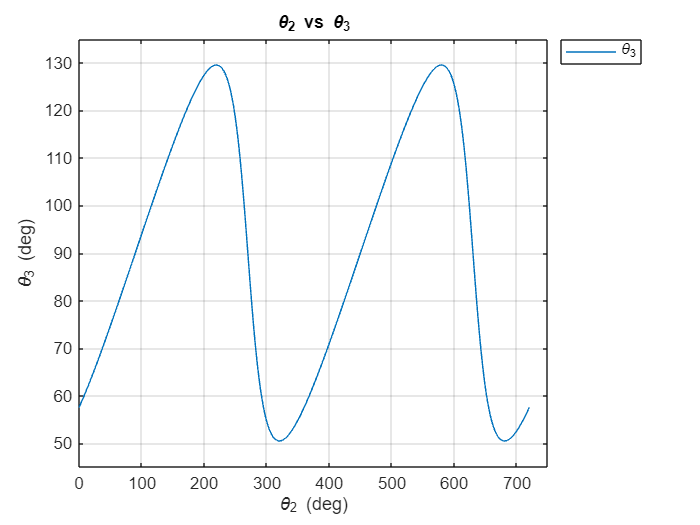

figure;
plot(rad2deg(theta2),rad2deg(teta3-pi))
xlim([0, 750]);
ylim([45, 135]);
grid on
legend('\theta_3','Location','northeastoutside')
title('\theta_2 vs \theta_3')
xlabel("\theta_2 (deg)")
ylabel("\theta_3 (deg)")

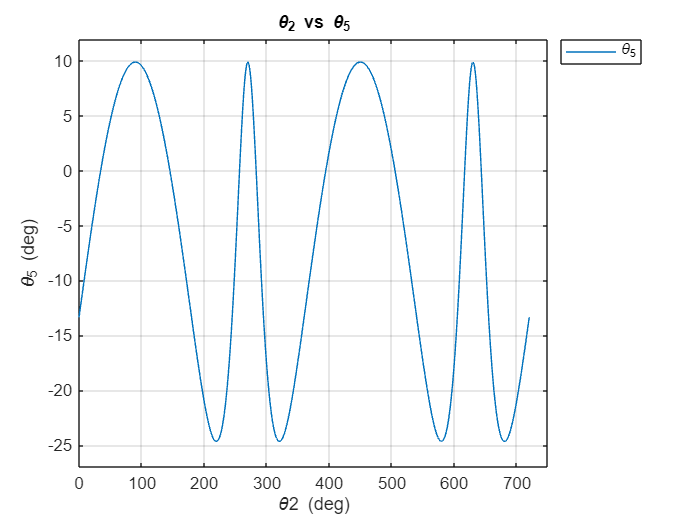

figure;
plot(rad2deg(theta2),rad2deg(teta5-pi))
xlim([0, 750]);
ylim([-27, 12]);
grid on
legend('\theta_5','Location','northeastoutside')
title('\theta_2 vs \theta_5')
xlabel("\theta2 (deg)")
ylabel("\theta_5 (deg)")

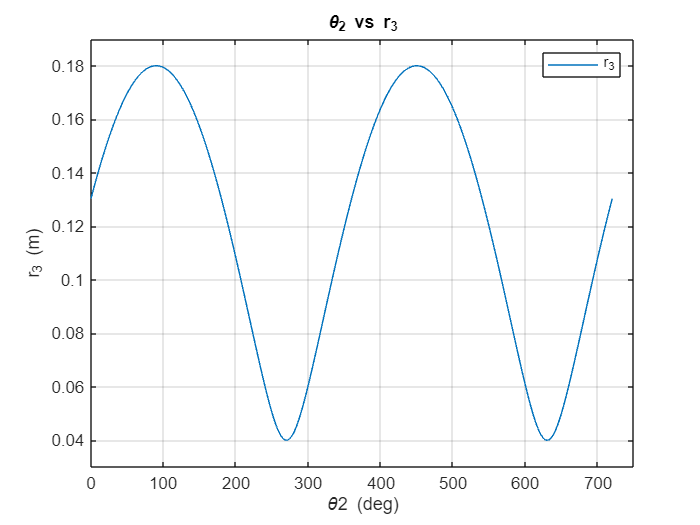


figure;
plot(rad2deg(theta2),r3);
xlim([0, 750]);
ylim([0.03 0.19]);
grid on;
legend('r_3')
title('\theta_2 vs r_3')
xlabel("\theta2 (deg)")
ylabel("r_3 (m)")

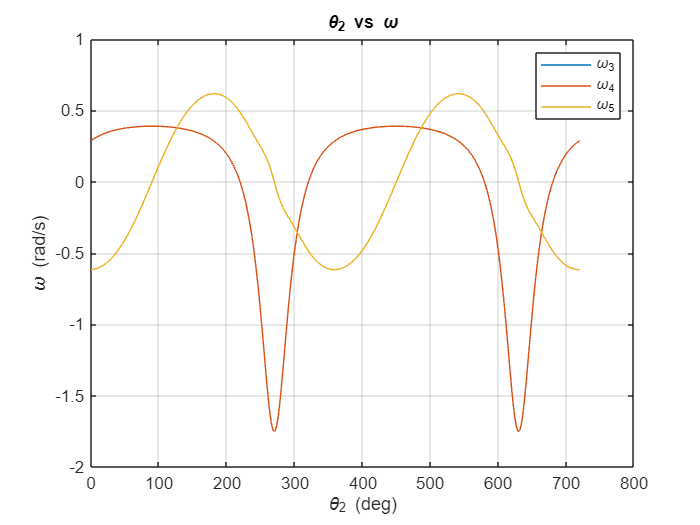


figure;
plot(rad2deg(theta2),w3)
hold on
plot(rad2deg(theta2),w4)
hold on
plot(rad2deg(theta2),w5)
hold off
grid on
legend('\omega_3','\omega_4','\omega_5')
title('\theta_2 vs \omega')
xlabel("\theta_2 (deg)")
ylabel("\omega (rad/s)")

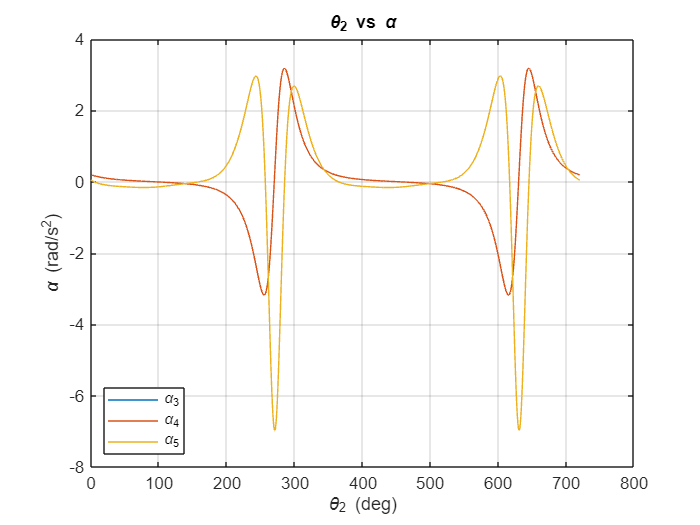


figure;
plot(rad2deg(theta2),a3)
hold on
plot(rad2deg(theta2),a4)
hold on
plot(rad2deg(theta2),a5)
hold off
grid on
legend('\alpha_3','\alpha_4','\alpha_5','Location','southwest')
title('\theta_2 vs \alpha')
xlabel("\theta_2 (deg)")
ylabel("\alpha (rad/s^2)")

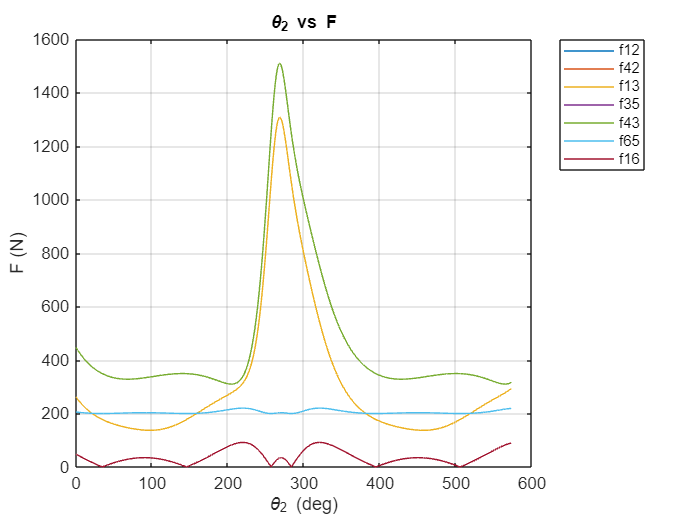


figure;
m_index=1591;
plot(rad2deg(theta2(1:m_index)),f12)
hold on
plot(rad2deg(theta2(1:m_index)),f42)
hold on
plot(rad2deg(theta2(1:m_index)),f13)
hold on
plot(rad2deg(theta2(1:m_index)),f35)
hold on
plot(rad2deg(theta2(1:m_index)),f43)
hold on
plot(rad2deg(theta2(1:m_index)),f65)
hold on
plot(rad2deg(theta2(1:m_index)),f16)
hold off
grid on
legend('f12','f42','f13','f35','f43','f65','f16','Location','northeastoutside')
title('\theta_2 vs F')
xlabel("\theta_2 (deg)")
ylabel("F (N)")

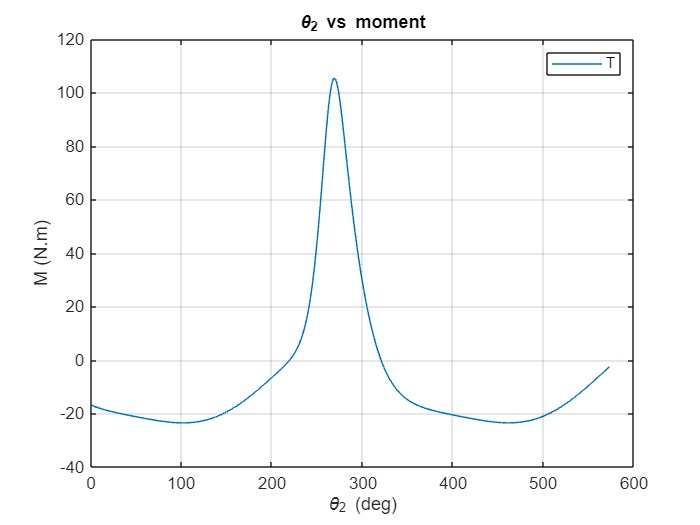


figure;
plot(rad2deg(theta2(1:m_index)),T)
grid on
legend('T')
title('\theta_2 vs moment')
xlabel("\theta_2 (deg)")
ylabel("M (N.m)")

ANIMATION

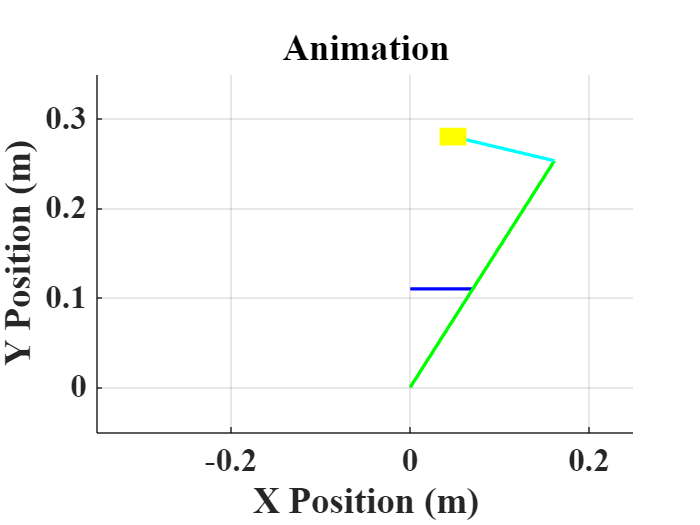

figure;
axis equal;
grid on;
hold on;
Xlabel='X Position (m)';
Ylabel='Y Position (m)';
xlabel(Xlabel, 'FontName', 'Times New Roman', 'FontSize', 24, 'FontWeight', 'bold');
ylabel(Ylabel, 'FontName', 'Times New Roman', 'FontSize', 24, 'FontWeight', 'bold');
Title='Animation';
title(Title, 'FontName', 'Times New Roman', 'FontSize', 30, 'FontWeight', 'bold');
set(gca, 'FontSize', 20, 'FontName', 'Times New Roman', 'FontWeight', 'bold');

xlim([-0.35, 0.25]);
ylim([-0.05, 0.35]); 

l2_plot = plot(0, 0, 'b', 'LineWidth', 2);  
l3_plot = plot(0, 0, 'g', 'LineWidth', 2);  
l4_plot = plot(0, 0, 'r', 'LineWidth', 5);  
l5_plot = plot(0, 0, 'c', 'LineWidth', 2);  

rectWidth4 = 0.03; % Width of slider 4
rectHeight4 = 0.015; % Height of slider 4

rectWidth6 = 0.03; % Width of slider 4
rectHeight6 = 0.02; % Height of slider 4

rect_plot = rectangle('Position', [0, 0, rectWidth6, rectHeight6], 'FaceColor', 'y', 'EdgeColor', 'none');
for i = 1:N
    hold on
    set(l2_plot, 'XData', [p_O2(1), p_B(i,1)], 'YData', [p_O2(2), p_B(i,2)]);
    set(l3_plot, 'XData', [p_O3(1), p_C(i,1)], 'YData', [p_O3(2), p_C(i,2)]);
    set(l5_plot, 'XData', [p_C(i,1), p_D(i,1)], 'YData', [p_C(i,2), p_D(i,2)]);
    set(rect_plot, 'Position', ...
        [-rectWidth6/2 + p_D(i,1), -rectHeight6/2 + p_D(i,2), rectWidth6, rectHeight6]);

    % Pause for animation effect
    hold off
    pause(0.01)
end

hold off;            